clear

% Read img file
img = imread("db/DB1/db1_03.jpg")

img = 512×385×3 uint8 array
img(:,:,1) =

   217   218   218   216   217   218   218   217   218   218   219   219   219   219   218   218   220   218   218   219   219   218   217   218   221   220   220   221   220   218   219   221   223   222   219   219   219   219   219   219   220   218   222   221   219   219   236   193   189   230   212   210   200   203   191   193   212   223   221   218   217   216   219   218   218   219   221   228   231   205   154   241   225   222   219   219   220   222   221   219   219   221   220   221   223   221   220   222   220   220   220   220   220   220   220   220   220   220   220   219   219   219   219   219   218   219   219   219   219   219   219   219   219   219   219   218   217   217   218   220   218   218   218   218   217   217   217   217   218   217   217   216   216   216   216   217   216   215   215   215   215   216   216   216   214   216   216   215   213   212   212   215   213   213   214   212   214   216   216   2


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.0783    0.0783    0.0783    0.0783    0.0783    0.0783    0.0783    0.0783    0.0790    0.0790    0.0785    0.0785    0.0785    0.0785    0.0790    0.0794    0.0781    0.0787    0.0787    0.0781    0.0781    0.0787    0.0795    0.0807    0.0808    0.0808    0.0808    0.0808    0.0808    0.0814    0.0808    0.0808    0.0814    0.0814    0.0804    0.0804    0.0808    0.0850    0.0970    0.0981    0.0973    0.0990    0.0995    0.0995    0.0995    0.0995    0.1011    0.1008    0.1033    0.1036
    0.0783    0.0783    0.0783    0.0783    0.0783    0.0783    0.0778    0.0783    0.0790    0.0790    0.0785    0.0800    0.0800    0.0800    0.0806    0.0806    0.0793    0.0798    0.0798    0.0793    0.0793    0.0798    0.0810    0.0805    0.0812    0.0808    0.0808    0.0808    0.0808    0.0814    0.0808    0.0808    0.0814    0.0814    0.0808    0.0804    0.0808    0.0850    0.0981    0.0981    0.0990    0.0995    0.0995    0.0995    0.0995    0.0995    0.1011    0.1008    0.1033  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 512×385 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   



imshow(eye_mask);

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 388

y = 209

[indexX,indexY] = eye_index(eye_mask)

indexX =    53.7116  125.1625  265.4460  338.1895


indexY =   238.6554  246.8168  249.4993  248.1471



% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    67.9608   73.2351  139.8680  145.9010


sorted_mid_indices =      2     3     1     4



% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

closest_mid_eye_indices =      2     3


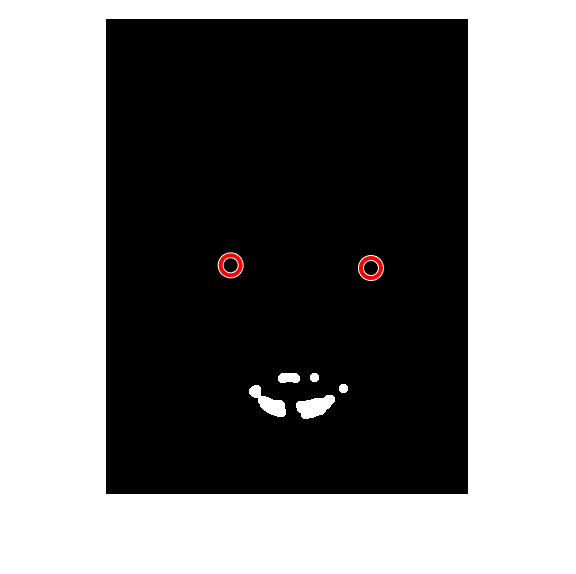

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

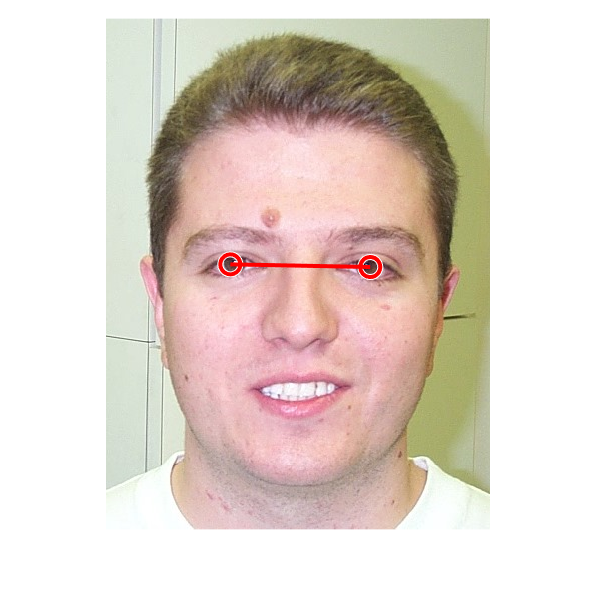


eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')